# Graficos PID

close all; clc, clear
% Datos
m = 1.6;
km = log(1-0.9933)/-0.1;
Ix = 0.021915027;
Iy = 0.022124548;
Iz = 0.042349865;

mot = tf(km,[1 km]);
s = tf('s');

## Altura

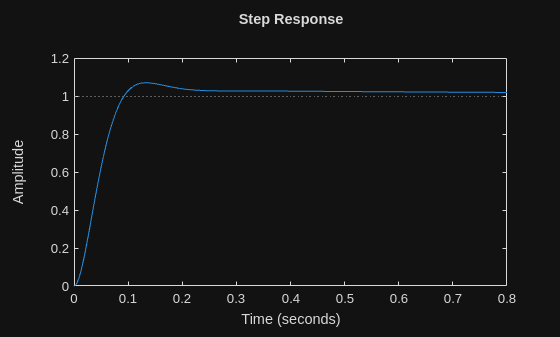

sys = series(mot,tf(1,[m 0 0]));
% pid = 38.213*(s+0.3831)^2/s
pid = (38.21*s^2+29.28*s+0.8)/s;
step(feedback(series(pid,sys),1))

## Roll

sys = series(mot,tf(1,[Ix 0 0]));
pid = 0.2*(s+0.08)*(s+5)/s


pid =
 
  0.2 s^2 + 1.016 s + 0.08
  ------------------------
             s
 
Continuous-time transfer function.


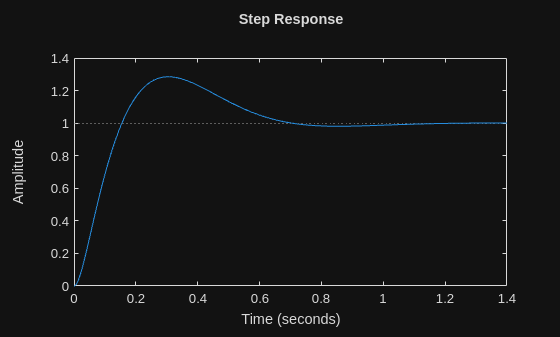

step(feedback(series(pid,sys),1))

## Pitch

sys = series(mot,tf(1,[Iy 0 0]));
pid = 0.63911*(s+4.041)*(s+0.4543)/s


pid =
 
  0.6391 s^2 + 2.873 s + 1.173
  ----------------------------
               s
 
Continuous-time transfer function.


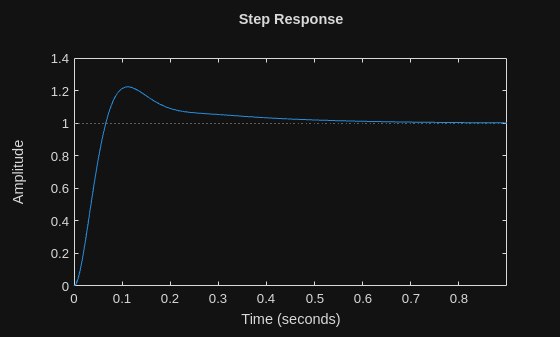

step(feedback(series(pid,sys),1))

## Yaw

sys = series(mot,tf(1,[Iz 0 0]));
pid = 2.2878*(s+0.7276)^2/s


pid =
 
  2.288 s^2 + 3.329 s + 1.211
  ---------------------------
               s
 
Continuous-time transfer function.


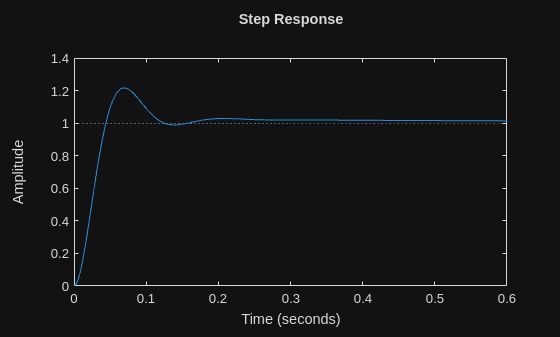

step(feedback(series(pid,sys),1))